clear; close all
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% output 0 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
syms M m l g u z z_dot theta theta_dot t q1 q2

% define the system state
x = [z; z_dot; theta; theta_dot];

% define system dynamics
y_ddot=(-m*l*sin(theta)*theta_dot^2 + m*g*sin(theta)*cos(theta) + u)/...
    (M + m*sin(theta)^2);
theta_ddot=(-m*l*sin(theta)*cos(theta)*theta_dot^2 + (M+m)*g*sin(theta) +...
    u*cos(theta))/...
    (l*(M+m*sin(theta)^2));

xdot = [z_dot; y_ddot; theta_dot;theta_ddot]

$$xdot = \left(\begin{array}{c} \dot{z}\\ \frac{-l\,m\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}+u+g\,m\,\cos\left(\theta \right)\,\sin\left(\theta \right)}{m\,{\sin\left(\theta \right)}^{2}+M}\\ \dot{\theta }\\ \frac{-l\,m\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}+u\,\cos\left(\theta \right)+g\,\sin\left(\theta \right)\,\left(M+m\right)}{l\,\left(m\,{\sin\left(\theta \right)}^{2}+M\right)} \end{array}\right)$$



% define the set of parameters specific to our ODE
base_params.M = 1.0731;
base_params.m = 0.2300;
base_params.l= 0.3302;
base_params.g = 9.8;

%linearization starts here

% equilibrium point
x_bar = [0; 0; 0; 0];
u_bar = 0;

% find jacobian for any point x
A_raw = jacobian(xdot,x);
B_raw = jacobian(xdot,u);

% substitute parameters as defined above
A_specific = subs(subs(subs(subs(A_raw,m,base_params.m),M,base_params.M), l, base_params.l), g, base_params.g);
B_specific = subs(subs(subs(subs(B_raw,m,base_params.m),M,base_params.M), l, base_params.l), g, base_params.g);

% find jacobian around the equilibrium point
A = subs(subs(A_specific,x,x_bar), u, u_bar)

$$A = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & \frac{460}{219} & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & \frac{13031000}{361569} & 0 \end{array}\right)$$

B = subs(subs(B_specific,x,x_bar), u, u_bar)

$$B = \left(\begin{array}{c} 0\\ \frac{10000}{10731}\\ 0\\ \frac{50000000}{17716881} \end{array}\right)$$

C = [1, 0, 0, 0;
    0, 0, 1, 0]         % can only observe z and theta, not their velocities

C =      1     0     0     0
     0     0     1     0


Qo = obsv(A,C)

Qo =     1.0000         0         0         0
         0         0    1.0000         0
         0    1.0000         0         0
         0         0         0    1.0000
         0         0    2.1005         0
         0         0   36.0401         0
         0         0         0    2.1005
         0         0         0   36.0401


rank_Qo = rank(Qo)

rank_Qo = 4


observable = rank_Qo == size(x, 1)          % returns 1 if the system is observable

observable = logical
   1



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% output 1 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
A_double = double(A);
B_double = double(B);
C_double = C;

% desiging observer matrix L
poles_L_1 = [-10, -11, -12, -13];
poles_L_2 = [-40, -41, -42, -43];

negK_L_1 = place(A_double', C_double',poles_L_1);
negK_L_2 = place(A_double', C_double',poles_L_2);
K_L_1 = -negK_L_1;               % to convert to the convention used in class
K_L_2 = -negK_L_2;               % to convert to the convention used in class

L_1 = K_L_1'

L_1 =   -22.9338   -1.0388
 -130.7798  -14.0775
   -0.9570  -23.0662
  -10.9830 -168.2589


L_2 = K_L_2'

L_2 = 	1.0e+03 *

   -0.0829   -0.0011
   -1.7161   -0.0464
   -0.0009   -0.0831
   -0.0380   -1.7629



% verifies that our observer matrices place poles at correct locations
sort(eig(A_double + L_1 * C_double), 'descend') 

ans =   -10.0000
  -11.0000
  -12.0000
  -13.0000


sort(eig(A_double + L_2 * C_double), 'descend') 

ans =   -40.0000
  -41.0000
  -42.0000
  -43.0000




% desigining controller matrix K
poles_K = [-5.1, -5.2, -5.3, -5.4];
negK = place(A_double, B_double, poles_K);
K = -negK;

% verifies pole placement of controller matrix K
sort(eig(A_double + B_double*K), 'descend') 

ans =    -5.1000
   -5.2000
   -5.3000
   -5.4000


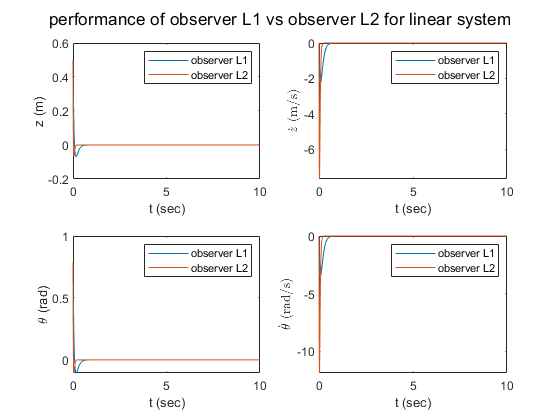




% preparing for simulations
x0 = [-0.5; 0; -pi/4; 0];
xhat0 = [0; 0; 0; 0];
x0_gen = [x0; xhat0];    % concatenate initial conditions to simulate simultaneously

options = odeset('RelTol',1e-7,'AbsTol',1e-7); 
Tspan = linspace(0,10,1e3);                      %choose time span from 0 to 1 because error dies out quickly


linearized_params.A = A_double;
linearized_params.B = B_double;
linearized_params.C= C_double;
linearized_params.K = K;


% define parameters for L1 and simulate for linear system
linearized_params.L = L_1;
[t_L1, x_gen_L1]=ode45(@state_estimate_dynamics_linear,Tspan,x0_gen,options, linearized_params);
z_error_L1 = x_gen_L1(:,5) - x_gen_L1(:,1);
zdot_error_L1 = x_gen_L1(:,6) - x_gen_L1(:,2);
theta_error_L1 = x_gen_L1(:,7) - x_gen_L1(:,3);
thetadot_error_L1 = x_gen_L1(:,8) - x_gen_L1(:,4);


% define parameters for L2 and simulate for linear system
linearized_params.L = L_2;
[t_L2, x_gen_L2]=ode45(@state_estimate_dynamics_linear,Tspan,x0_gen,options, linearized_params);
z_error_L2 = x_gen_L2(:,5) - x_gen_L2(:,1);
zdot_error_L2 = x_gen_L2(:,6) - x_gen_L2(:,2);
theta_error_L2 = x_gen_L2(:,7) - x_gen_L2(:,3);
thetadot_error_L2 = x_gen_L2(:,8) - x_gen_L2(:,4);


% plotting a figure with 4 subplots for linear system
figure
subplot(2,2,1)              % plotting z
plot(t_L1, z_error_L1)
hold on                     
plot(t_L2, z_error_L2)
legend('observer L1', 'observer L2')
xlabel("t (sec)")
ylabel("z (m)")
title('Error for state variable $z$', 'Interpreter','latex')

subplot(2,2,2)              % plotting z_dot
plot(t_L1, zdot_error_L1)
hold on                     
plot(t_L2, zdot_error_L2)
legend('observer L1', 'observer L2')
xlabel("t (sec)")
ylabel("$\dot{z}$ (m/s)", 'Interpreter','latex')
title('Error for state variable $\dot{z}$', 'Interpreter','latex')

subplot(2,2,3)              % plotting theta
plot(t_L1, theta_error_L1)
hold on                     
plot(t_L2, theta_error_L2)
legend('observer L1', 'observer L2')
xlabel("t (sec)")
ylabel("\theta (rad)")
title('Error for state variable $\theta$', 'Interpreter','latex')

subplot(2,2,4)              % plotting theta_dot
plot(t_L1, thetadot_error_L1)
hold on                     
plot(t_L2, thetadot_error_L2)
legend('observer L1', 'observer L2')
xlabel("t (sec)")
ylabel("$\dot{\theta}$ (rad/s)", 'Interpreter','latex')
title('Error for state variable $\dot{\theta}$', 'Interpreter','latex')
set(gcf,'units','points','position',[0,0,800,500])
sgtitle('State Estimation Error for Noiseless Linear model of Cart-Pendulum System with Observer Gains $L_1$ and $L_2$', 'Interpreter','latex')

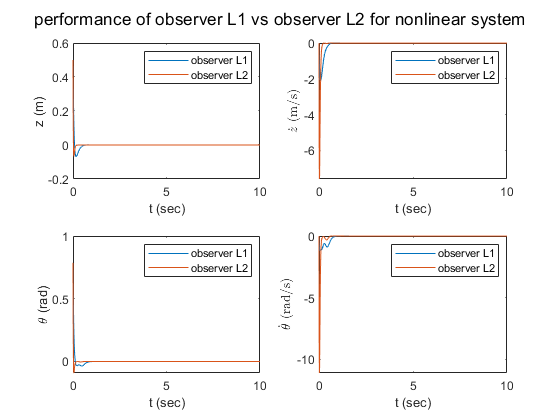




% prepare base paramaeters for nonlinear system
nonlinear_params = base_params;
nonlinear_params.A = A_double;
nonlinear_params.B = B_double;
nonlinear_params.C= C_double;
nonlinear_params.K = K;


% define parameters for L1 and simulate for nonlinear system
nonlinear_params.L = L_1;
[t_L1, x_gen_L1]=ode45(@state_estimate_dynamics_nl,Tspan,x0_gen,options, nonlinear_params);
z_error_L1 = x_gen_L1(:,5) - x_gen_L1(:,1);
zdot_error_L1 = x_gen_L1(:,6) - x_gen_L1(:,2);
theta_error_L1 = x_gen_L1(:,7) - x_gen_L1(:,3);
thetadot_error_L1 = x_gen_L1(:,8) - x_gen_L1(:,4);


% define parameters for L2 and simulate for nonlinear system
nonlinear_params.L = L_2;
[t_L2, x_gen_L2]=ode45(@state_estimate_dynamics_nl,Tspan,x0_gen,options, nonlinear_params);
z_error_L2 = x_gen_L2(:,5) - x_gen_L2(:,1);
zdot_error_L2 = x_gen_L2(:,6) - x_gen_L2(:,2);
theta_error_L2 = x_gen_L2(:,7) - x_gen_L2(:,3);
thetadot_error_L2 = x_gen_L2(:,8) - x_gen_L2(:,4);

% plotting a figure with 4 subplots for nonlinear system
figure
subplot(2,2,1)              % plotting z
plot(t_L1, z_error_L1)
hold on                     
plot(t_L2, z_error_L2)
legend('observer L1', 'observer L2')
xlabel("t (sec)")
ylabel("z (m)")
title('Error for state variable $z$', 'Interpreter','latex')
subplot(2,2,2)              % plotting z_dot
plot(t_L1, zdot_error_L1)
hold on                     
plot(t_L2, zdot_error_L2)
legend('observer L1', 'observer L2')
xlabel("t (sec)")
ylabel("$\dot{z}$ (m/s)", 'Interpreter','latex')
title('Error for state variable $\dot{z}$', 'Interpreter','latex')
subplot(2,2,3)              % plotting theta
plot(t_L1, theta_error_L1)
hold on                     
plot(t_L2, theta_error_L2)
legend('observer L1', 'observer L2')
xlabel("t (sec)")
ylabel("\theta (rad)")
title('Error for state variable $\theta$', 'Interpreter','latex')
subplot(2,2,4)              % plotting theta_dot
plot(t_L1, thetadot_error_L1)
hold on                     
plot(t_L2, thetadot_error_L2)
legend('observer L1', 'observer L2')
xlabel("t (sec)")
ylabel("$\dot{\theta}$ (rad/s)", 'Interpreter','latex')
title('Error for state variable $\dot{\theta}$', 'Interpreter','latex')
set(gcf,'units','points','position',[0,0,800,500])
sgtitle('State Estimation Error for Noiseless Non-Linear model of Cart-Pendulum System with Observer Gains $L_1$ and $L_2$', 'Interpreter','latex')


% observation: 
% the observation error of the linear system is generally smaller and
% decay at a smoother rate than the observation error of the nonlinear
% system for both observation matrices (L1 and L2). In both secnarios, L2
% performs significantly better than L1 in the long run (because the error
% decays at a much faster rate). However, the maximum error of L2 is also
% significantly worse (larger) than L1's


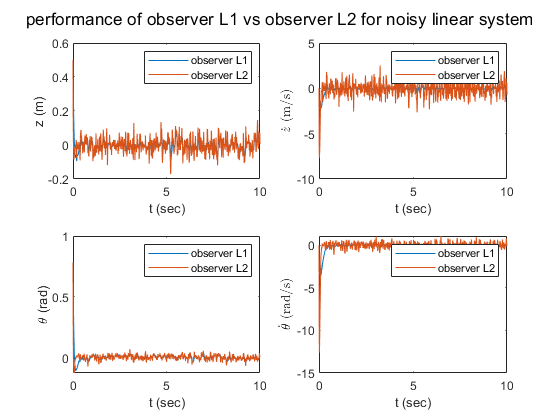

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% output 2 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
cov_mat = [0.005 0;
            0 0.001];
L_upper = chol(cov_mat);
L_lower = L_upper';
radm_seed = randn(2, 1000);          
radn_vector = L_lower * radm_seed;   % 1000 random column vectors with zero mean and unit variance


W = @(t) interp1(Tspan, radn_vector', t);  % transpose radn_vector to use interp1. Function returns a row vector


linear_noisy_params.A = A_double;
linear_noisy_params.B = B_double;
linear_noisy_params.C= C_double;
linear_noisy_params.K = K;
linear_noisy_params.W = W;


% define parameters for L1 and simulate for nonlinear system
linear_noisy_params.L = L_1;
[t_L1, x_gen_L1]=ode45(@state_estimate_dynamics_linear_noisy,Tspan,x0_gen,options, linear_noisy_params);
z_error_L1 = x_gen_L1(:,5) - x_gen_L1(:,1);
zdot_error_L1 = x_gen_L1(:,6) - x_gen_L1(:,2);
theta_error_L1 = x_gen_L1(:,7) - x_gen_L1(:,3);
thetadot_error_L1 = x_gen_L1(:,8) - x_gen_L1(:,4);


% define parameters for L2 and simulate for nonlinear system
linear_noisy_params.L = L_2;
[t_L2, x_gen_L2]=ode45(@state_estimate_dynamics_linear_noisy,Tspan,x0_gen,options, linear_noisy_params);
z_error_L2 = x_gen_L2(:,5) - x_gen_L2(:,1);
zdot_error_L2 = x_gen_L2(:,6) - x_gen_L2(:,2);
theta_error_L2 = x_gen_L2(:,7) - x_gen_L2(:,3);
thetadot_error_L2 = x_gen_L2(:,8) - x_gen_L2(:,4);

% plotting a figure with 4 subplots for nonlinear system
figure
subplot(2,2,1)              % plotting z
plot(t_L1, z_error_L1)
hold on                     
plot(t_L2, z_error_L2)
legend('observer L1', 'observer L2')
xlabel("t (sec)")
ylabel("z (m)")
title('Error for state variable $z$', 'Interpreter','latex')

subplot(2,2,2)              % plotting z_dot
plot(t_L1, zdot_error_L1)
hold on                     
plot(t_L2, zdot_error_L2)
legend('observer L1', 'observer L2')
xlabel("t (sec)")
ylabel("$\dot{z}$ (m/s)", 'Interpreter','latex')
title('Error for state variable $\dot{z}$', 'Interpreter','latex')

subplot(2,2,3)              % plotting theta
plot(t_L1, theta_error_L1)
hold on                     
plot(t_L2, theta_error_L2)
legend('observer L1', 'observer L2')
xlabel("t (sec)")
ylabel("\theta (rad)")
title('Error for state variable $\theta$', 'Interpreter','latex')

subplot(2,2,4)              % plotting theta_dot
plot(t_L1, thetadot_error_L1)
hold on                     
plot(t_L2, thetadot_error_L2)
legend('observer L1', 'observer L2')
xlabel("t (sec)")
ylabel("$\dot{\theta}$ (rad/s)", 'Interpreter','latex')
title('Error for state variable $\dot{\theta}$', 'Interpreter','latex')
set(gcf,'units','points','position',[0,0,800,500])
sgtitle('State Estimation Error for Noisy Linear model of Cart-Pendulum System with Observer Gains $L_1$ and $L_2$', 'Interpreter','latex')


% obtain the MSE of the final 5sec of each component of each simulation
z_L1_errors = z_error_L1(t_L1 > t_L1(end) - 5);
z_L1_MSE = sum(z_L1_errors.^2)/length(z_L1_errors)

z_L1_MSE = 8.4349e-04

z_L2_errors = z_error_L2(t_L2 > t_L2(end) - 5);
z_L2_MSE = sum(z_L2_errors.^2)/length(z_L2_errors)

z_L2_MSE = 0.0024


zdot_L1_errors = zdot_error_L1(t_L1 > t_L1(end) - 5);
zdot_L1_MSE = sum(zdot_L1_errors.^2)/length(zdot_L1_errors)

zdot_L1_MSE = 0.0214

zdot_L2_errors = zdot_error_L2(t_L2 > t_L2(end) - 5);
zdot_L2_MSE = sum(zdot_L2_errors.^2)/length(zdot_L2_errors)

zdot_L2_MSE = 0.7487


theta_L1_errors = theta_error_L1(t_L1 > t_L1(end) - 5);
theta_L1_MSE = sum(theta_L1_errors.^2)/length(theta_L1_errors)

theta_L1_MSE = 1.9036e-04

theta_L2_errors = theta_error_L2(t_L2 > t_L2(end) - 5);
theta_L2_MSE = sum(theta_L2_errors.^2)/length(theta_L2_errors)

theta_L2_MSE = 4.3562e-04


thetadot_L1_errors = thetadot_error_L1(t_L1 > t_L1(end) - 5);
thetadot_L1_MSE = sum(thetadot_L1_errors.^2)/length(thetadot_L1_errors)

thetadot_L1_MSE = 0.0083

thetadot_L2_errors = thetadot_error_L2(t_L2 > t_L2(end) - 5);
thetadot_L2_MSE = sum(thetadot_L2_errors.^2)/length(thetadot_L2_errors)

thetadot_L2_MSE = 0.1348


% Discussion:
% the observation for L1 fluctuates with a smaller magnitude compared to
% the fluction of L2. However, system L2 still decays at a faster rate (as
% seen at the beginning of the simulation period)

% the MSE of L2 is larger than the MSE of L1 for all state components
% because large negative time constants (as achieved through pole
% placements cause the system to react faster to changes in the input
%(observation). Hence, more noise is picked up

% in terms of frequency response,assuming zero input, the transfer function
% becomes (note: Y is input, X is the state -output) is X/Y =  L/(A+LC -s).
% when L2 is designed such that the poles of A+LC is more negative, the
% amplitude of high prequency noise (large s) is amplified more
% drastically. Because noise is random, and high frequency, it has more
% impact in the system with observation matrix = L2

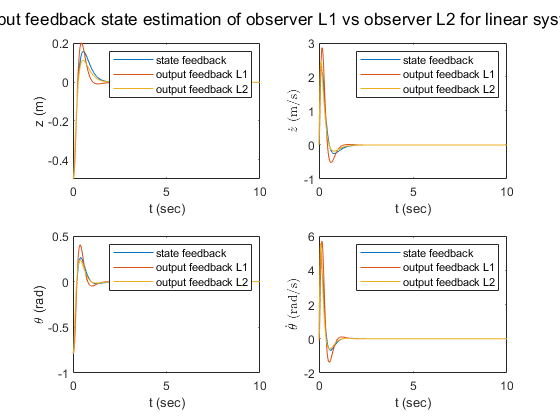

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% output 3 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% reuse lienarized_params from output 1
% preparing for simulations
x0 = [-0.5; 0; -pi/4; 0];
xhat0 = [0; 0; 0; 0];
x0_gen = [x0; xhat0];    % concatenate initial conditions to simulate simultaneously

% define parameters for L1 and simulate for linear system
linearized_params.L = L_1;
[t_L1, x_gen_output_L1]=ode45(@estimate_control_dynamics_linear,Tspan,x0_gen,options, linearized_params);

% define parameters for L2 and simulate for linear system
linearized_params.L = L_2;
[t_L2, x_gen_output_L2]=ode45(@estimate_control_dynamics_linear,Tspan,x0_gen,options, linearized_params);

% obtain state feedback states
[t_L1, x_gen_state]=ode45(@state_estimate_dynamics_linear,Tspan,x0_gen,options, linearized_params);
state_feedback_state = x_gen_state(:,1:4); % this is the same for both observer matrices

% plotting a figure with 4 subplots for linear system
figure
subplot(2,2,1)              % plotting z
plot(t_L1, state_feedback_state(:,1))
hold on                     
plot(t_L2, x_gen_output_L1(:,1))
plot(t_L2, x_gen_output_L2(:,1))
legend('State Feedback', 'Output Feedback with L1', 'Output Feedback with L2')
xlabel("t (sec)")
ylabel("z (m)")
title('Signal Response for state variable $z$', 'Interpreter','latex')

subplot(2,2,2)              % plotting z_dot
plot(t_L1, state_feedback_state(:,2))
hold on                     
plot(t_L2, x_gen_output_L1(:,2))
plot(t_L2, x_gen_output_L2(:,2))
legend('State Feedback', 'Output Feedback with L1', 'Output Feedback with L2')
xlabel("t (sec)")
ylabel("$\dot{z}$ (m/s)", 'Interpreter','latex')
title('Signal Response for state variable $\dot{z}$', 'Interpreter','latex')

subplot(2,2,3)              % plotting theta
plot(t_L1, state_feedback_state(:,3))
hold on                     
plot(t_L2, x_gen_output_L1(:,3))
plot(t_L2, x_gen_output_L2(:,3))
legend('State Feedback', 'Output Feedback with L1', 'Output Feedback with L2')
xlabel("t (sec)")
ylabel("\theta (rad)")
title('Signal Response for state variable $\theta$', 'Interpreter','latex')

subplot(2,2,4)              % plotting theta_dot
plot(t_L1, state_feedback_state(:,4))
hold on                     
plot(t_L2, x_gen_output_L1(:,4))
plot(t_L2, x_gen_output_L2(:,4))
legend('State Feedback', 'Output Feedback with L1', 'Output Feedback with L2')
xlabel("t (sec)")
ylabel("$\dot{\theta}$ (rad/s)", 'Interpreter','latex')
title('Signal Response for state variable $\dot{\theta}$', 'Interpreter','latex')
set(gcf,'units','points','position',[0,0,800,500])
sgtitle('Plant State Signal Responses for Noiseless Linear model with Observer Gains $L_1$ and $L_2$', 'Interpreter','latex')

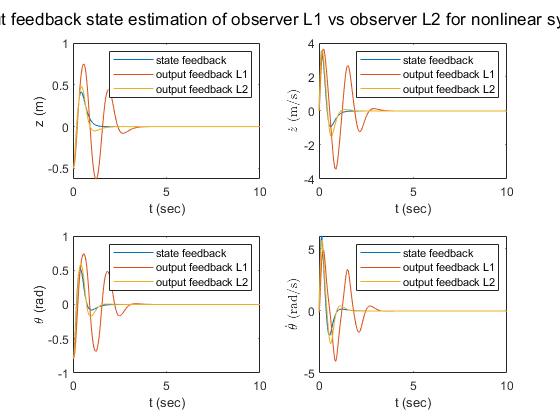

% nonlinear output feedback control (reuse nonlinear_params from output1)

% define parameters for L1 and simulate for nonlinear system
nonlinear_params.L = L_1;
[t_L1, x_gen_output_L1]=ode45(@estimate_control_dynamics_nl,Tspan,x0_gen,options, nonlinear_params);

% define parameters for L2 and simulate for nonlinear system
nonlinear_params.L = L_2;
[t_L2, x_gen_output_L2]=ode45(@estimate_control_dynamics_nl,Tspan,x0_gen,options, nonlinear_params);

% obtain state feedback states
[t_L1, x_gen_state]=ode45(@state_estimate_dynamics_nl,Tspan,x0_gen,options, nonlinear_params);
state_feedback_state = x_gen_state(:,1:4); % this is the same for both observer matrices


% plotting a figure with 4 subplots for nonlinear system
figure
subplot(2,2,1)              % plotting z
plot(t_L1, state_feedback_state(:,1))
hold on                     
plot(t_L1, x_gen_output_L1(:,1))
plot(t_L2, x_gen_output_L2(:,1))
legend('State Feedback', 'Output Feedback with L1', 'Output Feedback with L2')
xlabel("t (sec)")
ylabel("z (m)")
title('Signal Response for state variable $z$', 'Interpreter','latex')
subplot(2,2,2)              % plotting z_dot
plot(t_L1, state_feedback_state(:,2))
hold on                     
plot(t_L1, x_gen_output_L1(:,2))
plot(t_L2, x_gen_output_L2(:,2))
legend('State Feedback', 'Output Feedback with L1', 'Output Feedback with L2')
xlabel("t (sec)")
ylabel("$\dot{z}$ (m/s)", 'Interpreter','latex')
title('Signal Response for state variable $\dot{z}$', 'Interpreter','latex')
subplot(2,2,3)              % plotting theta
plot(t_L1, state_feedback_state(:,3))
hold on                     
plot(t_L1, x_gen_output_L1(:,3))
plot(t_L2, x_gen_output_L2(:,3))
legend('State Feedback', 'Output Feedback with L1', 'Output Feedback with L2')
xlabel("t (sec)")
ylabel("\theta (rad)")
title('Signal Response for state variable $\theta$', 'Interpreter','latex')
subplot(2,2,4)              % plotting theta_dot
plot(t_L1, state_feedback_state(:,4))
hold on                     
plot(t_L1, x_gen_output_L1(:,4))
plot(t_L2, x_gen_output_L2(:,4))
legend('State Feedback', 'Output Feedback with L1', 'Output Feedback with L2')
xlabel("t (sec)")
ylabel("$\dot{\theta}$ (rad/s)", 'Interpreter','latex')
title('Signal Response for state variable $\dot{\theta}$', 'Interpreter','latex')
set(gcf,'units','points','position',[0,0,800,500])
sgtitle('Plant State Signal Responses for Noiseless Non-Linear model with Observer Gains $L_1$ and $L_2$', 'Interpreter','latex')



% Discussion

% linear plant
%   output feedback vs state feedback:
% all 3 systems generally have similar settling time. The amount of
% overshoot of output feedback with observer gain L2 is generally smaller
% than that of the state feedback system whilst output feedback with 
% observer gain L1 has the lartest overshoot of all.

% (not required) I speculate that this is because the optimal control in
% the nonlinear system is more gradual compared to the behavior of the
% state-feedback controller. Because the state estimation lags behind the
% actual state signal, the controller response of the output feedback system is
% more gradual, and optimal.


% when the observer convergence is larger (L2), the plant state signal 
% resembles the state feedback state signals much more closely in comparison 
% to the state signal of the observer with slower convergence (L1). In this
% case, we define closeness metric by a combination of the resemblance of
% the overhall shape of the state signal's trajectories, and the gap between
% the state signals trajectories. This behavior is as expected.

% nonlinear plant
% with larger observer convergence speed (as when we use L2), the state
% signal tracks the state signal of the state-feedback nonlinear system
% much closely than when the observer convergence speed is lower. In fact,
% as convergence speed lowers (L1), the controlled state signal starts to
% oscillate dramatically. This suggests by not being able to estimate the
% state well, the controller won't be able to control the system optimally.





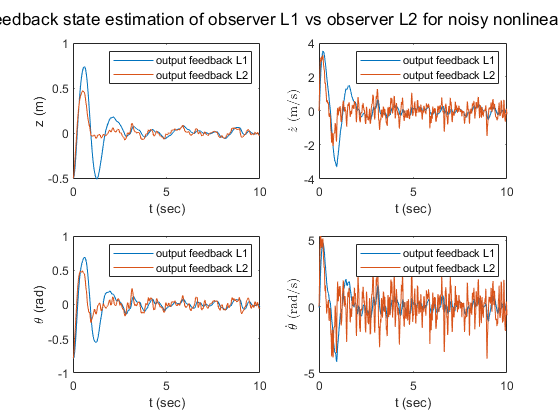

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% output 4 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
nl_noisy_params = nonlinear_params;
nl_noisy_params.W = W;


% define parameters for L1 and simulate for nonlinear system
nl_noisy_params.L = L_1;
[t_L1, x_gen_output_L1]=ode45(@estimate_control_dynamics_nl_noisy,Tspan,x0_gen,options, nl_noisy_params);

% define parameters for L2 and simulate for nonlinear noisy system
nl_noisy_params.L = L_2;
[t_L2, x_gen_output_L2]=ode45(@estimate_control_dynamics_nl_noisy,Tspan,x0_gen,options, nl_noisy_params);

% plotting a figure with 4 subplots for nonlinear system
figure
subplot(2,2,1)              % plotting z
plot(t_L2, x_gen_output_L1(:,1))
hold on                     
plot(t_L2, x_gen_output_L2(:,1))
legend('Output Feedback with L1', 'Output Feedback with L2')
xlabel("t (sec)")
ylabel("z (m)")
title('Signal Response for state variable $z$', 'Interpreter','latex')
subplot(2,2,2)              % plotting z_dot
plot(t_L2, x_gen_output_L1(:,2))
hold on                     
plot(t_L2, x_gen_output_L2(:,2))
legend('Output Feedback with L1', 'Output Feedback with L2')
xlabel("t (sec)")
ylabel("$\dot{z}$ (m/s)", 'Interpreter','latex')
title('Signal Response for state variable $\dot{z}$', 'Interpreter','latex')
subplot(2,2,3)              % plotting theta
plot(t_L2, x_gen_output_L1(:,3))
hold on                     
plot(t_L2, x_gen_output_L2(:,3))
legend('Output Feedback with L1', 'Output Feedback with L2')
xlabel("t (sec)")
ylabel("\theta (rad)")
title('Signal Response for state variable $\theta$', 'Interpreter','latex')
subplot(2,2,4)              % plotting theta_dot
plot(t_L2, x_gen_output_L1(:,4))
hold on                     
plot(t_L2, x_gen_output_L2(:,4))
legend('Output Feedback with L1', 'Output Feedback with L2')
xlabel("t (sec)")
ylabel("$\dot{\theta}$ (rad/s)", 'Interpreter','latex')
title('Signal Response for state variable $\dot{\theta}$', 'Interpreter','latex')
set(gcf,'units','points','position',[0,0,800,500])
sgtitle('Plant State Signal Responses for Noisy Linear model with Observer Gains $L_1$ and $L_2$', 'Interpreter','latex')



% (extra, for discussion) 
% regulation MSE calculation wrt equilirbium point at (0,0,0,0)
z_error_L1 = 0 - x_gen_output_L1(:,1);
zdot_error_L1 = 0 - x_gen_output_L1(:,2);
theta_error_L1 = 0 - x_gen_output_L1(:,3);
thetadot_error_L1 = 0 - x_gen_output_L1(:,4);

z_error_L2 = 0 - x_gen_output_L2(:,1);
zdot_error_L2 = 0 - x_gen_output_L2(:,2);
theta_error_L2 = 0 - x_gen_output_L2(:,3);
thetadot_error_L2 = 0 - x_gen_output_L2(:,4);

z_L1_errors = z_error_L1(t_L1 > t_L1(end) - 5);
regulation_z_L1_MSE = sum(z_L1_errors.^2)/length(z_L1_errors)

regulation_z_L1_MSE = 0.0012

z_L2_errors = z_error_L2(t_L2 > t_L2(end) - 5);
regulation_z_L2_MSE = sum(z_L2_errors.^2)/length(z_L2_errors)

regulation_z_L2_MSE = 0.0010


zdot_L1_errors = zdot_error_L1(t_L1 > t_L1(end) - 5);
regulation_zdot_L1_MSE = sum(zdot_L1_errors.^2)/length(zdot_L1_errors)

regulation_zdot_L1_MSE = 0.0300

zdot_L2_errors = zdot_error_L2(t_L2 > t_L2(end) - 5);
regulation_zdot_L2_MSE = sum(zdot_L2_errors.^2)/length(zdot_L2_errors)

regulation_zdot_L2_MSE = 0.1299


theta_L1_errors = theta_error_L1(t_L1 > t_L1(end) - 5);
regulation_theta_L1_MSE = sum(theta_L1_errors.^2)/length(theta_L1_errors)

regulation_theta_L1_MSE = 0.0015

theta_L2_errors = theta_error_L2(t_L2 > t_L2(end) - 5);
regulation_theta_L2_MSE = sum(theta_L2_errors.^2)/length(theta_L2_errors)

regulation_theta_L2_MSE = 0.0028


thetadot_L1_errors = thetadot_error_L1(t_L1 > t_L1(end) - 5);
regulation_thetadot_L1_MSE = sum(thetadot_L1_errors.^2)/length(thetadot_L1_errors)

regulation_thetadot_L1_MSE = 0.1258

thetadot_L2_errors = thetadot_error_L2(t_L2 > t_L2(end) - 5);
regulation_thetadot_L2_MSE = sum(thetadot_L2_errors.^2)/length(thetadot_L2_errors)

regulation_thetadot_L2_MSE = 0.9718



% state estimation MSE
z_error_L1 = x_gen_output_L1(:,5) - x_gen_output_L1(:,1);
zdot_error_L1 = x_gen_output_L1(:,6) - x_gen_output_L1(:,2);
theta_error_L1 = x_gen_output_L1(:,7) - x_gen_output_L1(:,3);
thetadot_error_L1 = x_gen_output_L1(:,8) - x_gen_output_L1(:,4);

z_error_L2 = x_gen_output_L2(:,5) - x_gen_output_L2(:,1);
estimation_zdot_error_L2 = x_gen_output_L2(:,6) - x_gen_output_L2(:,2);
theta_error_L2 = x_gen_output_L2(:,7) - x_gen_output_L2(:,3);
estimation_thetadot_error_L2 = x_gen_output_L2(:,8) - x_gen_output_L2(:,4);

z_L1_errors = z_error_L1(t_L1 > t_L1(end) - 5);
estimation_z_L1_MSE = sum(z_L1_errors.^2)/length(z_L1_errors)

estimation_z_L1_MSE = 5.3124e-04

z_L2_errors = z_error_L2(t_L2 > t_L2(end) - 5);
estimation_z_L2_MSE = sum(z_L2_errors.^2)/length(z_L2_errors)

estimation_z_L2_MSE = 0.0017


zdot_L1_errors = zdot_error_L1(t_L1 > t_L1(end) - 5);
estimation_zdot_L1_MSE = sum(zdot_L1_errors.^2)/length(zdot_L1_errors)

estimation_zdot_L1_MSE = 0.0130

zdot_L2_errors = zdot_error_L2(t_L2 > t_L2(end) - 5);
estimation_zdot_L2_MSE = sum(zdot_L2_errors.^2)/length(zdot_L2_errors)

estimation_zdot_L2_MSE = 0.1299


theta_L1_errors = theta_error_L1(t_L1 > t_L1(end) - 5);
estimation_theta_L1_MSE = sum(theta_L1_errors.^2)/length(theta_L1_errors)

estimation_theta_L1_MSE = 1.2576e-04

theta_L2_errors = theta_error_L2(t_L2 > t_L2(end) - 5);
estimation_theta_L2_MSE = sum(theta_L2_errors.^2)/length(theta_L2_errors)

estimation_theta_L2_MSE = 3.9286e-04


thetadot_L1_errors = thetadot_error_L1(t_L1 > t_L1(end) - 5);
estimation_thetadot_L1_MSE = sum(thetadot_L1_errors.^2)/length(thetadot_L1_errors)

estimation_thetadot_L1_MSE = 0.0058

thetadot_L2_errors = thetadot_error_L2(t_L2 > t_L2(end) - 5);
estimation_thetadot_L2_MSE = sum(thetadot_L2_errors.^2)/length(thetadot_L2_errors)

estimation_thetadot_L2_MSE = 0.9718




% Discussion:
% effect of noise: noise causes a lot of disruptive movement along the
% trajectories of the state signals. This makes sense because measurement
% noise means that the input signal is corrupted

% with larger convergence speed, observer L2 converges (to within the
% vicinity of the equilibrium point) much quicker, but also fluctuate
% around this equilibrium point with larger magnitude (as seen in the case
% of z\dot and theta\dot. 

% To consolidate this point, we conducted the RMSE analysis on each state
% signal, demonstrating the large sensitivity to input noise of controller
% with large observer gain (L2). This is because large gains, as achieved 
% through pole placements, cause the system to react faster to changes in
% the input (observation). Hence, more noise is picked up. moew detailed
% discussion is found in section 3.2

%interesting POINT!!!
% However, the difference in regulation MSE between L1 and L2 system wasn't as
% dramatic as the estimation MSE (which we also calculated above) because small
% convergence speed also has its flaws: not being able to track the state signal 
% well means that the control signal is lagged, and suboptimal. This reduces 
% the difference in regulation EMS error between observer L1 and L2. 



